# Expand Example 3.7:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

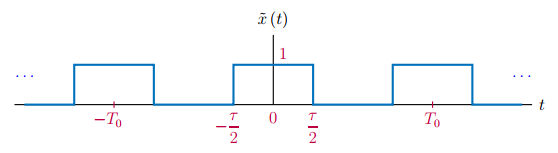

The duty cycle forthe pulse train shown is $d=\frac{\tau}{T_{0}}$.  EFS coefficients are

$c_{k}=d\,\textrm{sinc}(kd)$                    (3.78)

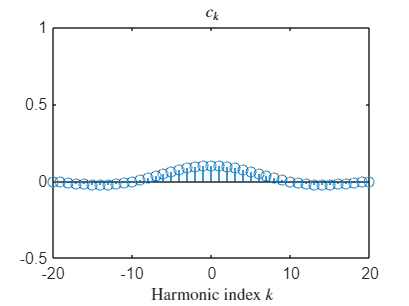

d = 0.1; % Duty cycle
%
c = @(k,d) d*sinc(k*d);  % Anonymous function for the EFS coefficients
k = [-20:20];            % Vector of harmonic indices.
% Compute and graph EFS coefficients
stem(k,c(k,d));
axis([-20,20,-0.5,1]);
set(0,'defaultTextInterpreter','latex');
xlabel('Harmonic index $k$');
title('$c_{k}$');

set(0,'defaultTextInterpreter','tex');